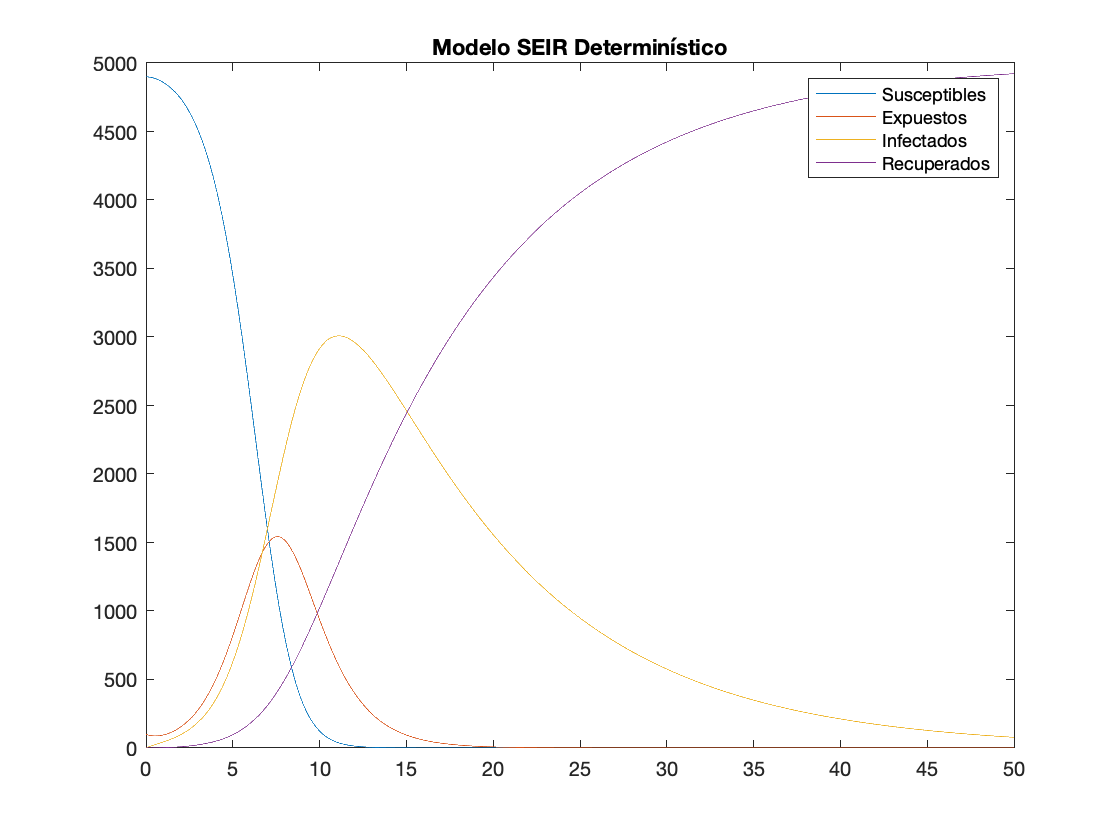

clear;
rng(1) % Semilla random para repetitividad

% Valores iniciales de susceptibles, expuestos, infectados y recuperados
x0 = [4899, 100, 1, 0];

% Vector temporal
tspan = (0:0.01:50);

% Resuelve la ecuación diferencial del modelo SEIR
[t, x] = ode45(@miODE, tspan, x0);

% Grafica la solución del modelo SEIR por ODE45
figure;
plot(t, x(:, 1));
hold on
plot(t, x(:, 2));
plot(t, x(:, 3));
plot(t, x(:, 4));
title('Modelo SEIR Determinístico');
legend('Susceptibles', 'Expuestos', 'Infectados', 'Recuperados');
hold off

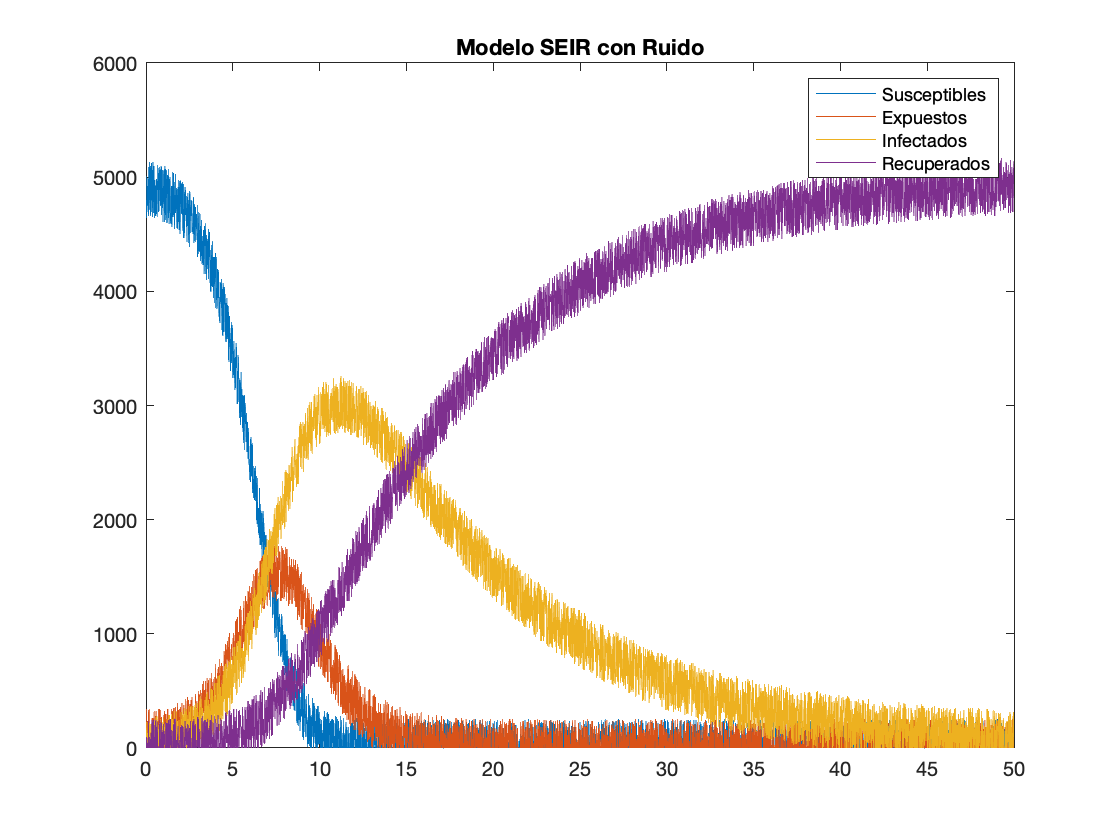


% Nivel de ruido deseado
ruido_maestro = 0.05;

% Generación de números aleatorios con parámetros de ± ruido maestro
a = -1 * ruido_maestro;
b = ruido_maestro;

ruido_S = (b - a) * rand(length(x(:, 1)), 1) + a;
ruido_E = (b - a) * rand(length(x(:, 2)), 1) + a;
ruido_I = (b - a) * rand(length(x(:, 3)), 1) + a;
ruido_R = (b - a) * rand(length(x(:, 4)), 1) + a;

% Construcción de susceptibles, expuestos, infectados y recuperados con ruido
S_ruido = x(:, 1) + ruido_S .* sum(x0);
S_ruido = round(S_ruido);

E_ruido = x(:, 2) + ruido_E .* sum(x0);
E_ruido = round(E_ruido);

I_ruido = x(:, 3) + ruido_I .* sum(x0);
I_ruido = round(I_ruido);

R_ruido = x(:, 4) + ruido_R .* sum(x0);
R_ruido = round(R_ruido);

% Corrección en caso de valores negativos
verdadero = true;
while verdadero
    for i = 1:length(x(:, 1))
        if S_ruido(i) < 0
            S_ruido(i) = S_ruido(i) - S_ruido(i);
            if I_ruido < R_ruido
                R_ruido = R_ruido + S_ruido(i);
            else
                I_ruido = I_ruido + S_ruido(i);
            end
        elseif E_ruido(i) < 0
            E_ruido(i) = E_ruido(i) - E_ruido(i);
            if S_ruido < I_ruido + R_ruido
                R_ruido = R_ruido + E_ruido(i);
            else
                S_ruido = S_ruido + E_ruido(i);
            end
        elseif I_ruido(i) < 0
            I_ruido(i) = I_ruido(i) - I_ruido(i);
            if S_ruido < E_ruido + R_ruido
                R_ruido = R_ruido + I_ruido(i);
            else
                E_ruido = E_ruido + I_ruido(i);
            end
        elseif R_ruido(i) < 0
            R_ruido(i) = R_ruido(i) - R_ruido(i);
            if S_ruido < E_ruido + I_ruido
                I_ruido = I_ruido + R_ruido(i);
            else
                E_ruido = E_ruido + R_ruido(i);
            end
        end
    end
    if min(I_ruido) < 0 || min(R_ruido) < 0 || min(S_ruido) < 0 || min(E_ruido) < 0
        verdadero = true;
    else
        verdadero = false;
    end
end

% Grafica de las funciones con ruido
figure;
plot(t, S_ruido);
hold on
plot(t, E_ruido);
plot(t, I_ruido);
plot(t, R_ruido);
title('Modelo SEIR con Ruido');
legend('Susceptibles', 'Expuestos', 'Infectados', 'Recuperados');
hold off

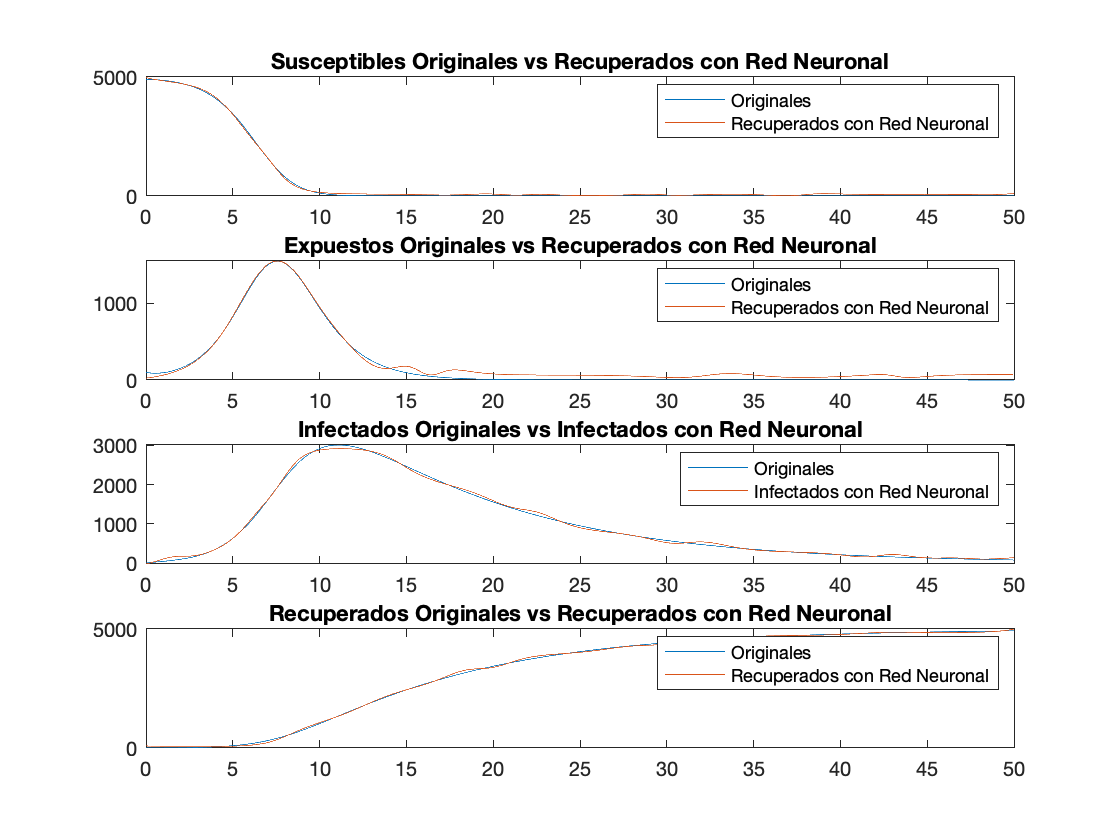


% Redes neuronales
net_S = red_neuronal(S_ruido);
net_E = red_neuronal(E_ruido);
net_I = red_neuronal(I_ruido);
net_R = red_neuronal(R_ruido);

% Comparación con funciones originales
figure;
subplot(4, 1, 1);
plot(t, x(:, 1));
hold on
plot(t, net_S);
title('Susceptibles Originales vs Recuperados con Red Neuronal');
legend('Originales', 'Recuperados con Red Neuronal');
hold off

subplot(4, 1, 2);
plot(t, x(:, 2));
hold on
plot(t, net_E);
title('Expuestos Originales vs Recuperados con Red Neuronal');
legend('Originales', 'Recuperados con Red Neuronal');
hold off

subplot(4, 1, 3);
plot(t, x(:, 3));
hold on
plot(t, net_I);
title('Infectados Originales vs Infectados con Red Neuronal');
legend('Originales', 'Infectados con Red Neuronal');
hold off

subplot(4, 1, 4);
plot(t, x(:, 4));
hold on
plot(t, net_R);
title('Recuperados Originales vs Recuperados con Red Neuronal');
legend('Originales', 'Recuperados con Red Neuronal');
hold off


% Cálculo de errores
error_susceptibles = sum(abs(x(:, 1) - net_S)) / length(net_S);
error_expuestos = sum(abs(x(:, 2) - net_E)) / length(net_E);
error_infectados = sum(abs(x(:, 3) - net_I)) / length(net_I);
error_recuperados = sum(abs(x(:, 4) - net_R)) / length(net_R);

disp(['Error en Susceptibles: ', num2str(error_susceptibles)]);

Error en Susceptibles: 52.4185


disp(['Error en Expuestos: ', num2str(error_expuestos)]);

Error en Expuestos: 46.4016


disp(['Error en Infectados: ', num2str(error_infectados)]);

Error en Infectados: 31.2917


disp(['Error en Recuperados: ', num2str(error_recuperados)]);

Error en Recuperados: 34.6889


function nett = red_neuronal(V_ruido)
    % Parámetros de la red neuronal
    factor_chistoso = 3;
    Neuronas_capas = 8;
    Capas = Neuronas_capas * ones(1, factor_chistoso);

    Entrenamiento = 'trainlm';
    net = feedforwardnet(Capas, Entrenamiento);

    % Funciones de activación
    net.layers{1:1:factor_chistoso}.transferFcn = 'logsig';

    % Epocas de entrenamiento
    net.trainParam.epochs = 200;

    % Datos de entrenamiento
    Ntest = 500;
    pd = makedist('Uniform', 0, length(V_ruido));
    xx = ceil(random(pd, 1, Ntest));
    ff = V_ruido(xx);

    % Entrenamiento de la red
    net = train(net, xx, ff');

    % Predicción de la red neuronal
    xs = 1:1:length(V_ruido);
    nett = net(xs)';
end

function dx = miODE(t, x)
    % Parámetros del modelo SEIR
    Beta = 1.8;
    Sigma = 0.5;
    Gamma = 0.1;
    N = x(1) + x(2) + x(3) + x(4);

    % Ecuaciones diferenciales del modelo SEIR
    dx(1) = -Beta * x(1) * x(3) / N;
    dx(2) = Beta * x(1) * x(3) / N - Sigma * x(2);
    dx(3) = Sigma * x(2) - Gamma * x(3);
    dx(4) = Gamma * x(3);

    dx = [dx(1); dx(2); dx(3); dx(4)];
end
